# **Performance Testing of Air Source Heat Pump (ASHP) System**

## 0. Setup

Code initiation

clc
clear
close all

set(0,'DefaultFigureWindowStyle','docked')

Load and Organize the data

clear data temp

data(1).d = readmatrix('Data 33F.xlsx', 'NumHeaderLines', 1);   % 33F
data(2).d = readmatrix('Data 36F.xlsx', 'NumHeaderLines', 1);   % 36F
data(3).d = readmatrix('Data 37F.xlsx', 'NumHeaderLines', 1);   % 37F
data(4).d = readmatrix('Data 38F.xlsx', 'NumHeaderLines', 1);   % 38F
data(5).d = readmatrix('Data 39F.xlsx', 'NumHeaderLines', 1);   % 39F
data(6).d = readmatrix('Data 40F.xlsx', 'NumHeaderLines', 1);   % 40F
data(7).d = readmatrix('Data 41F.xlsx', 'NumHeaderLines', 1);   % 41F

Conversions:

mpa = 145;  % psi to MPa
kgs = (3.7854)*(60)% gpm tp kg/s (using desnity of R410a)

kgs = 227.1240

Evaporator Outlet Temp/Compressor Inlet Temp:

for i = 1 : size(data,2)
    hp(i).evapoutcompin_temp = (mean(data(i).d(:,1)) - 32) * (5/9);
end

Condenser Inlet Temp

for i = 1 : size(data,2)
    hp(i).condin_temp = (mean(data(i).d(:,2)) - 32) * (5/9);
end

Room Temp

for i = 1 : size(data,2)
    hp(i).room_temp = (mean(data(i).d(:,3)) - 32) * (5/9);
end

Outdoor Temp

for i = 1 : size(data,2)
    hp(i).out_temp = (mean(data(i).d(:,4)) - 32) * (5/9);
end

Condenser Inlet Pressure

for i = 1 : size(data,2)
    hp(i).condin_pres = mean(data(i).d(:,5))/mpa;
end

Evaporator Exit Air Temp

for i = 1 : size(data,2)
    hp(i).evapexa_temp = (mean(data(i).d(:,6)) - 32) * (5/9);
end

Refrigerant Flow Rate (GPM)

for i = 1 : size(data,2)
    hp(i).rflowrate = mean(data(i).d(:,7))*kgs;
end

Condenser Outlet Pressure

for i = 1 : size(data,2)
    hp(i).condout_temp = mean(data(i).d(:,8))/mpa;
end

Condenser Outlet Temp

for i = 1 : size(data,2)
    hp(i).condin_temp = (mean(data(i).d(:,9)) - 32) * (5/9);
end

In this analysis, the data for 33F, 37F, and 41F will be used

hp(1)

ans = struct with fields:
    evapoutcompin_temp: 0.4230
           condin_temp: 41.8643
             room_temp: 22.9169
              out_temp: 0.5709
           condin_pres: 2.1501
          evapexa_temp: 29.4190
             rflowrate: 386.1108
          condout_temp: 2.0289


hp(3)

ans = struct with fields:
    evapoutcompin_temp: 1.7857
           condin_temp: 46.0816
             room_temp: 23.2982
              out_temp: 2.7740
           condin_pres: 2.3324
          evapexa_temp: 31.1763
             rflowrate: 334.5842
          condout_temp: 2.1924


hp(7)

ans = struct with fields:
    evapoutcompin_temp: 4.3054
           condin_temp: 50.6291
             room_temp: 23.9005
              out_temp: 4.9616
           condin_pres: 2.4507
          evapexa_temp: 40.6202
             rflowrate: 363.3984
          condout_temp: 2.3107


## 1. Calculate Heating Capacity

Heating Capacity:

## 
$$Q_h = \dot{m}_r \left( h_{2,r} - h_{3
,r} \right)$$


Where,

- $h_{2,r}$ = Refrigerant Enthalpy at Compressor Outlet/Condensor Inlet

- $h_{3,r}$ = Refrigerant Enthalpy at Condenser Outlet

- $\dot{m}_r$ = Refrigerant flowrate

Enthalpy is found from the following P-h diagram of R410A refrigerant (example for: Data 1, 33F outdoor temp):

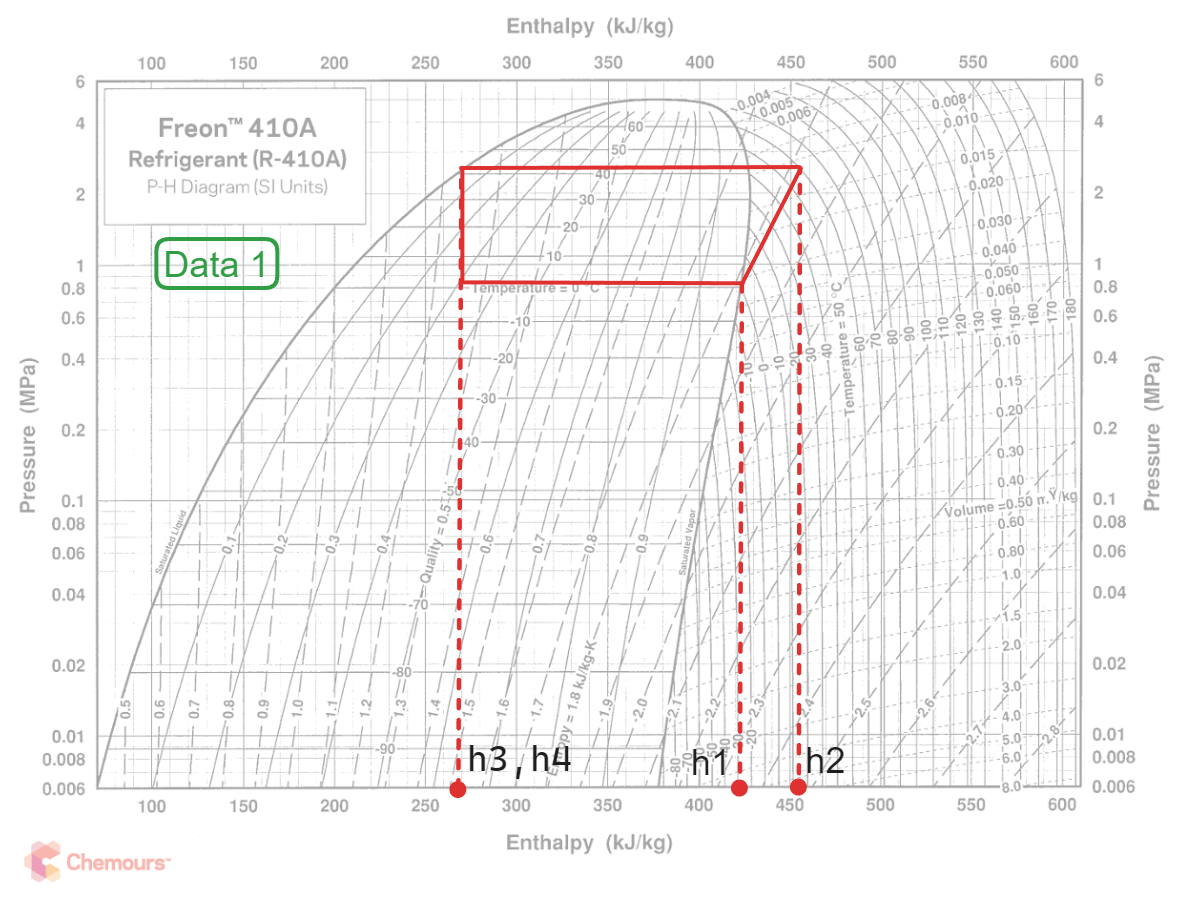

h2_33 = 455;    % kJ/kG
h3_33 = 265;    % kJ/kG
Q = hp(1).rflowrate * (h2_33 - h3_33); % kJ/s = kiloWatts

Q = 7.3361e+04

## 2.  Calculate Coefficient Of Performance 

Coefficient of Performance (COP):

## 
$$COP = \frac{\dot{m}_r \left( h_{2,r} - h_{3
,r} \right)}{W_{c,in}}$$


Where,

- $W_{c,in}$ = Compressor Power Input

## 3. Plot Q vs. COP

Compute uncertainty of the temperature measurement based on 60 samples and add error bars to the $T_{ss}(x)$ plot.

## 5. All MATLAB Calculations

In Appendix B, show the sample of all calculations done in MATLAB.

%{

Just export this livescript as  matlab script or word document

%}